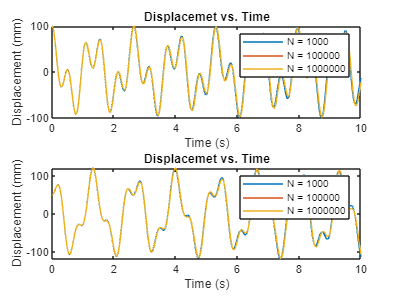

m1 = 0.0917;
m2 = 0.0765;
k1 = 4.66;
k2 = 4.66;
A = [0 1 0 0; (-k1 - k2) / m1 0 (k2 / m1) 0; 0 0 0 1; (k2 / m2) 0 -(k2 / m2) 0];
Z0 = [100; 0; 50; 0];
T = 10;

[t, x1_de, x1_de_de, x2_de, x2_de_de] = IEMSolver(A, Z0, T, 10000);

steps = [1000, 100000, 1000000];
figure;
for step = 1:length(steps)
    [t, x1_de, x1_de_de, x2_de, x2_de_de] = IEMSolver(A, Z0, T, steps(step));
    subplot(2, 1, 1)
    plot(t, x1_de, "-", "DisplayName", "N = " + num2str(steps(step)))
    hold on
    subplot(2, 1, 2)
    plot(t, x2_de, "-", "DisplayName", "N = " + num2str(steps(step)))
    hold on
end

subplot(2, 1, 1)
legend show
xlabel("Time (s)")
ylabel("Displacement (mm)")
title("Displacemet vs. Time")

subplot(2, 1, 2)
legend show
xlabel("Time (s)")
ylabel("Displacement (mm)")
title("Displacemet vs. Time")

function [t, x1_de, x1_de_de, x2_de, x2_de_de] = IEMSolver(A, Z0, T, N)
    dt = T / N;
    t = 0:dt:T;
    sol = NaN(4, length(t));
    sol(:, 1) = Z0;
    for n = 2:length(t)
        sol(:, n) = sol(:, n - 1) + A * dt * sol(:, n - 1);
        sol(:, n) = sol(:, n - 1) + (dt / 2) * A * (sol(:, n - 1) + sol(:, n));
    end
    x1_de = sol(1, :);
    x1_de_de = sol(2, :);
    x2_de = sol(3, :);
    x2_de_de = sol(4, :);
end